# MATLAB and Simulink Robotics Arena: Using Sensor Fusion for Orientation Estimation - Inertial Measurement Unit

Copyright 2018 The MathWorks, Inc.

close all;
clear;

To run this script you will need to:

- Download [MATLAB Mobile](https://www.mathworks.com/products/matlab-mobile.html) to your Andriod device and configure MATLAB Mobile to connect with your computer. [Follow these steps to connect MATLAB Mobile on your Android device to MATLAB](matlab:web('https://www.mathworks.com/help/matlabmobile_android/ug/configure-matlab-mobile-on-an-android-device-to-connect-to-your-computer.html', '-browser'))

- Download the [MATLAB Support Package for Android Sensors](https://www.mathworks.com/hardware-support/android-sensor.html) 

## Connect to MATLAB Mobile

Connect MATLAB mobile to MATLAB and log sensor data to be fused

#### Start the connector to get data from the phone via the MATLAB mobile app 

connector on password;

MATLAB Connector is already running.


#### Define MOBILEDEV object and enable sensor data streaming

AndroidPhone = mobiledev;
AndroidPhone.SampleRate = 100;
AndroidPhone.AngularVelocitySensorEnabled = 1;
AndroidPhone.OrientationSensorEnabled = 1;
AndroidPhone.AccelerationSensorEnabled = 1;
AndroidPhone.MagneticSensorEnabled = 1;

loggingTime = 10; % seconds

#### Log 'loggingTime' seconds of phone sensor data 

AndroidPhone.Logging = 1;
pause(loggingTime);
[a, ta] = accellog(AndroidPhone);
[w, tw] = angvellog(AndroidPhone);
[m, tm] = magfieldlog(AndroidPhone);
[oin, to] = orientlog(AndroidPhone);

#### Stop logging

AndroidPhone.Logging = 0;

## Sensor Fusion

#### Make sure that the time vector has the minimum length that willl be matched with the orientation data (for plotting purpose only )

tfin = min([length(ta),length(tm),length(tw),length(to)]);
t = ta(1:tfin);

#### Define the IMU filter and assign sensors noise covariances

aFilter = imufilter('SampleRate',AndroidPhone.SampleRate); 
aFilter.GyroscopeNoise          = 0.0002;
aFilter.AccelerometerNoise      = 0.0006;
aFilter.LinearAccelerationNoise = 0.0025;

#### Align reference frames 

w(:,1) = -w(:,1);
w(:,2) = w(:,2);
w(:,3) = -w(:,3);
a(:,2) = -a(:,2);
a(:,3) = a(:,3);
qyaw = quaternion([sqrt(2)/2 0 0 sqrt(2)/2]);

#### Fusion processing loop

for i=1:length(t)
    % This is where the IMU fusion function is called
    orientation(i) = aFilter(a(i,:),w(i,:));
    
    % 90 deg rotation to match the phone frame
    orientation(i) = orientation(i)*qyaw;
    
    % Convert quaternion into Euler angles
    eulFilt(i,:)= euler(orientation(i),'ZYX','frame');
end

% Release the system object
release(aFilter)

inityaw = eulFilt(1,1)*180/pi-oin(1,1);

## Visualization

Plot the estimated orientations in Euler representation along with the orientation already provided by the phone

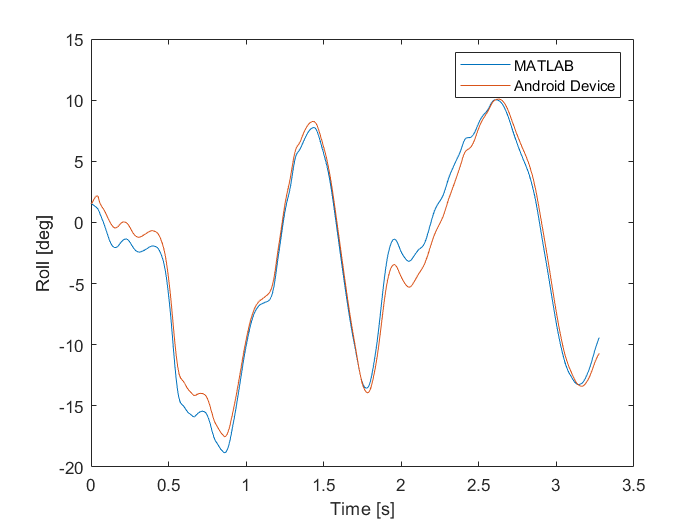

figure(1)
plot(t,eulFilt(:,3)*180/pi,t,oin((1:tfin),3));
xlabel('Time [s]');
ylabel('Roll [deg]');
legend('MATLAB', 'Android Device');

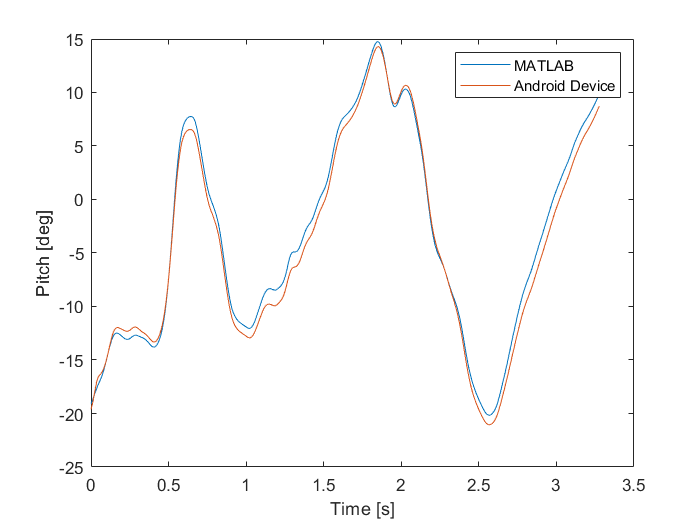

figure(2)
plot(t,-eulFilt(:,2)*180/pi,t,oin((1:tfin),2));
xlabel('Time [s]');
ylabel('Pitch [deg]');
legend('MATLAB', 'Android Device');

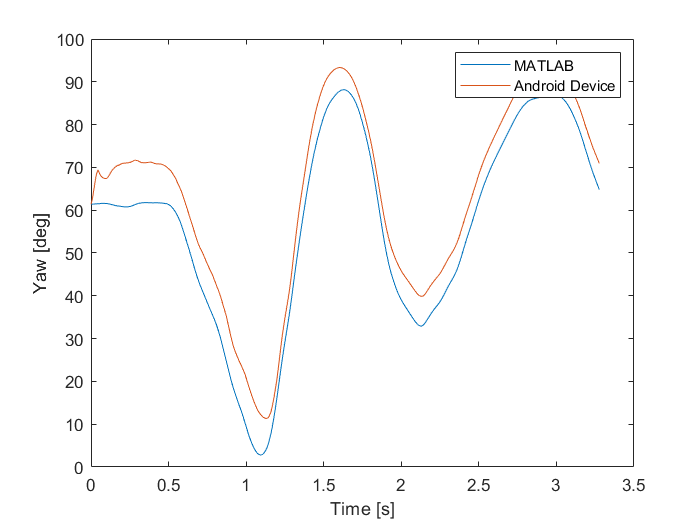

figure(3)
plot(t,eulFilt(:,1)*180/pi-inityaw,t,oin((1:tfin),1));
xlabel('Time [s]');
ylabel('Yaw [deg]');
legend('MATLAB', 'Android Device');